# Kalman Filter for Sail Boat

Cameron Wolfe 5/14/2023


$$I\ddot{\theta} = -\frac{rC_{\ell}Av^2}{2} - b\dot{\theta}$$



$$C_{\ell} = 2\pi\phi = \frac{2\pi^2}{180}\phi = k\phi$$



$$I\ddot{\theta}+b\dot{\theta} = -\frac{rA\pi^2v^2}{180}\phi$$



$$\Theta(Is^2+bs) = -\frac{rA\pi^2v^2}{180}\Phi$$



$$\frac{\Theta}{\Phi} = -\frac{rA\pi^2v^2}{180b}\frac{1}{\frac{I}{b}s^2 + s}$$



$$\frac{\Theta}{\Phi} = - \frac{K_b}{s(\tau s + 1)}$$


sysParams.m = 3.10;                      % Boat mass
sysParams.I = .25;                       % Boat MOI
sysParams.r = .4;                        % Distance to rudder
sysParams.dt = .01;                      % Time step
sysParams.ClPerAlpha = 2 * pi^2 / 180;   % Cl for rudder angle (deg)
sysParams.A = .07 * .125;                % Rudder area
sysParams.rho = 1000;                    % Water density
sysParams.b = 1;                        % Damping coefficient
sysParams.C = [eye(3) zeros(3);
               zeros(1,5) 1];

load("controller.mat")

controller = C;
controller2 = C;
controller2.k = controller2.k / 4;

disc_controller = tf(c2d(controller, sysParams.dt, 'tustin'))

disc_controller =
 
  -19.43 z + 18.67
  ----------------
     z - 0.9048
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


output_matrix = [cell2mat(disc_controller.Numerator), cell2mat(disc_controller.Denominator)];
output_matrix = output_matrix([1 2 4]);
writematrix(output_matrix, "controller.txt");

s = tf('s');


% Kb needs to be multiplied by v^2
sysParams.Kb = sysParams.r * sysParams.A * sysParams.rho * sysParams.ClPerAlpha / 2 / sysParams.b;
sysParams.tau = sysParams.I / sysParams.b; 

x0 = [0 0 0 1 0]';

timeSteps = 10000;
sysParams.dt = 0.01;

t = 0:sysParams.dt:timeSteps*sysParams.dt;

x = [x0 zeros(5, timeSteps)];
phi = 10 * randn(timeSteps);
C = eye(5);
y = zeros(5, timeSteps);


for i=1:timeSteps
    y(:,i) = C*x(:,i);
    x_dot = stateProp(x(:,i), phi(i), sysParams);
    x(:,i+1) = x(:, i) + x_dot * sysParams.dt;
end

Apar = partialF(x0, 1, sysParams)

Apar =     1.0000         0         0    0.0100         0
         0    1.0000   -0.0100    0.0000   -0.0000
         0         0    1.0000   -0.0001    0.0098
         0         0         0    1.0000         0
         0         0         0   -0.0150    0.9608


Cpar = partialG(x0, 1, sysParams)

Cpar =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


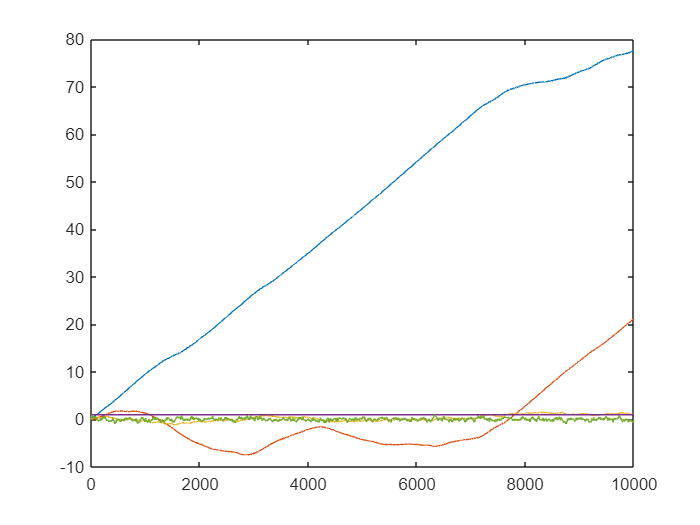


plot(y')

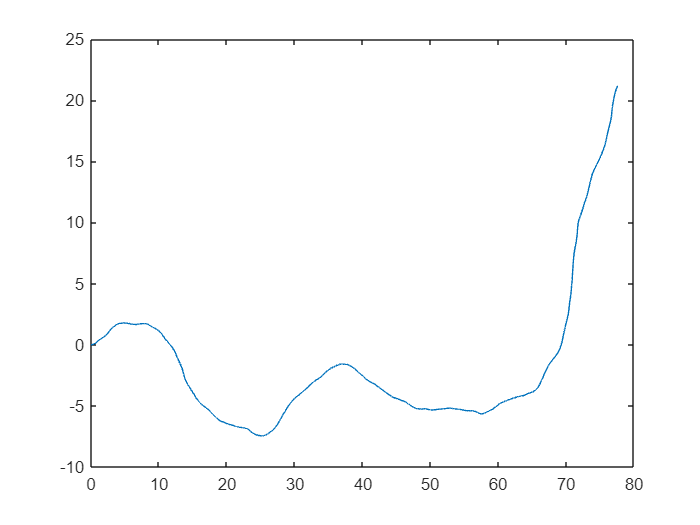


plot(x(1,:), x(2,:));

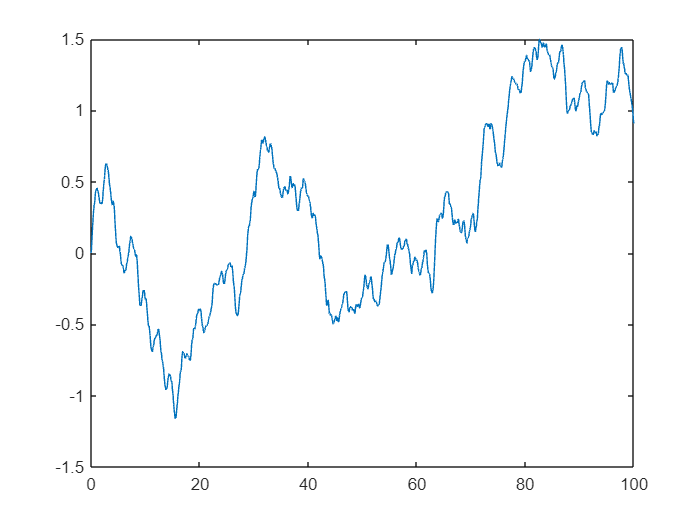

plot(t, x(3,:));

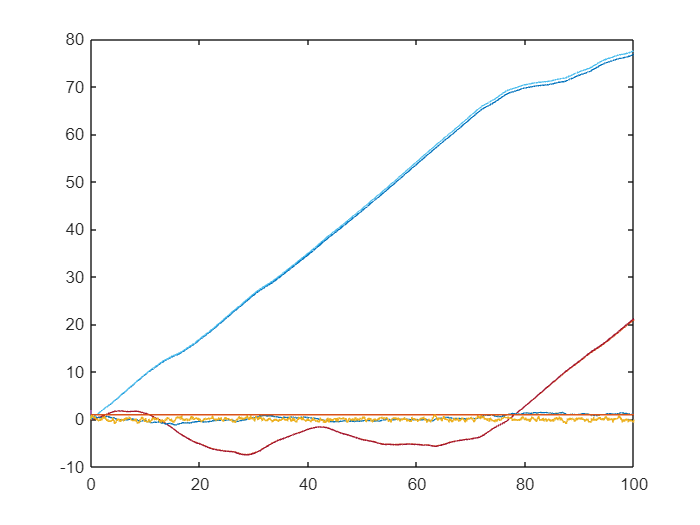

sys_tf = -sysParams.Kb/(s*(sysParams.tau*s+1));
partialG(1, 1);

x_hat = zeros(5, timeSteps+1);
x_hat(4, 1) = 2;

Q = 100*eye(5);
R = eye(5);
P = eye(5);

for i=1:timeSteps
    [x_hat(:,i+1), P] = kalmanFilter(x_hat(:,i), phi(i), y(:,i), Q, R, P, sysParams);
end

plot(t, x_hat);
hold on;
plot(t,x)
hold off;

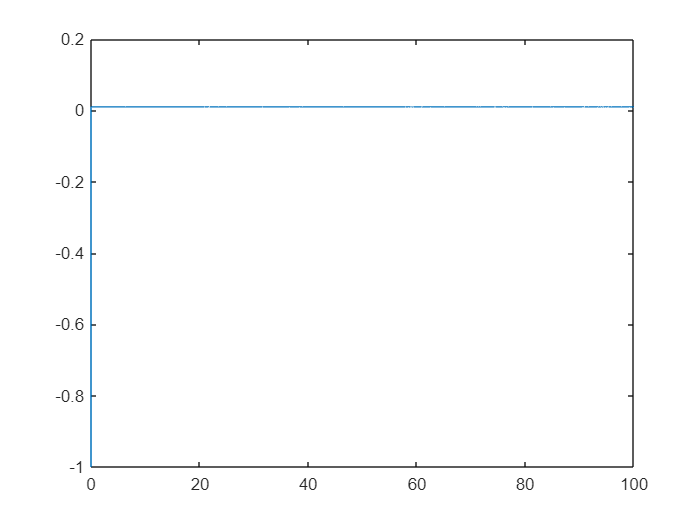

plot(t, x(4,:)-x_hat(4,:))

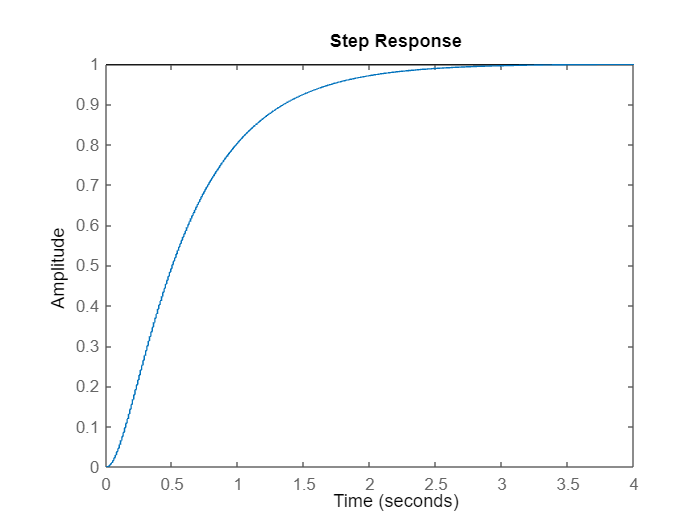

sys_tf_disc = c2d(sys_tf, sysParams.dt);
cl = feedback(disc_controller*sys_tf_disc, 1);
step(cl);

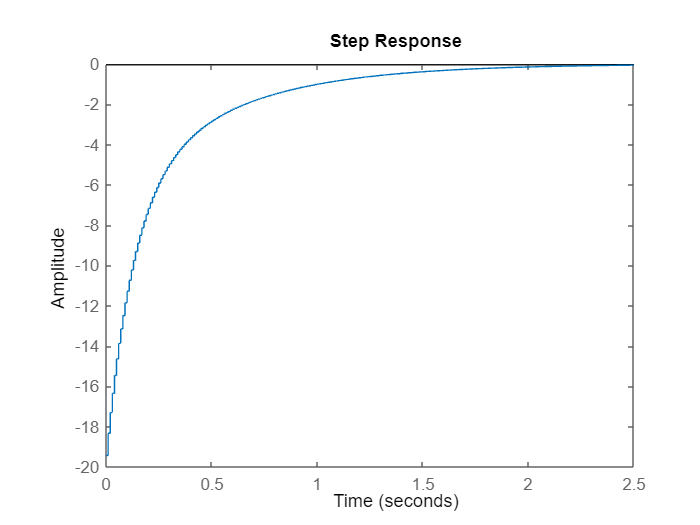

v_cl = feedback(disc_controller, sys_tf_disc);

step(v_cl);

function x_dot = stateProp(x, u, sysParams)
    X         = x(1);
    Y         = x(2);
    theta     = x(3);
    v_x       = x(4);
    theta_dot = x(5);

    phi = u;

    m = sysParams.m;
    I = sysParams.I;
    A = sysParams.A;
    cl = sysParams.ClPerAlpha * phi;
    rho = sysParams.rho;
    r = sysParams.r;
    b = sysParams.b;

    F_r = 1/2 * rho * A * cl * v_x^2;
    M_r = -r * F_r;

    X_dot = v_x * cos(theta);
    Y_dot = v_x * sin(theta);
    v_x_dot = 0;
    %theta_dot = theta_dot;
    theta_dot_dot = (M_r - b * theta_dot) / I;

    x_dot = [X_dot; Y_dot; theta_dot; v_x_dot; theta_dot_dot];
end

function A = partialF(x, u, sysParams)
    % Variable extraction
    X = x(1);
    Y = x(2);
    theta = x(3);
    Vx = x(4);
    theta_dot = x(5);

    b = sysParams.b;
    r = sysParams.r;
    I = sysParams.I;
    A = sysParams.A;
    rho = sysParams.rho;

    k = r * rho * A * pi^2 / 180;

    dt = sysParams.dt;

    phi = u;
    Apar = [0, 0, -Vx*sin(theta),    cos(theta),    0;
            0, 0, -Vx*cos(theta),    sin(theta),    0;
            0, 0,              0,             0,    1;
            0, 0,              0,             0,    0;
            0, 0,              0, -2*k/I*phi*Vx, -b/I];

    A = c2d(Apar, zeros(5,1), dt);
end

### partialG

Calculates $\frac{\partial g}{\partial x}$ which is used for EKF.

function C = partialG(x, u, sysParams)
    C = eye(5);
end

### getMeasurement

Performs measurement using system model (calculates $g(x(k))$).

function y = getMeasurement(x, u, sysParams)
    % Variable extraction
    X         = x(1,:);
    Y         = x(2,:);
    theta     = x(3,:);
    v_x       = x(4,:);
    theta_dot = x(5,:);

    y = x;
end

### kalmanFilter

Runs EKF.

function [xHatNew, P] = kalmanFilter(xHat, u, y, Q, R, P, sysParams)
    % Go from x(k) to x(k+1)
    xprime = stateProp(xHat, u, sysParams);

    % Linearize equations of motion about current state
    A = partialF(xprime, u, sysParams);

    % Update P matrix
    P = A * P * A' + Q;

    % Linearize measurement equation about current state
    C = partialG(xprime, u, sysParams);

    % Update L matrix
    L = P*C'*(R+C*P*C')^-1;

    % Correct propagated state using measurement
    xHatNew = xprime + L*(y - getMeasurement(xprime, u, sysParams));

    % Update P matrix
    P = (eye(size(Q,1)) - L*C)*P;
end